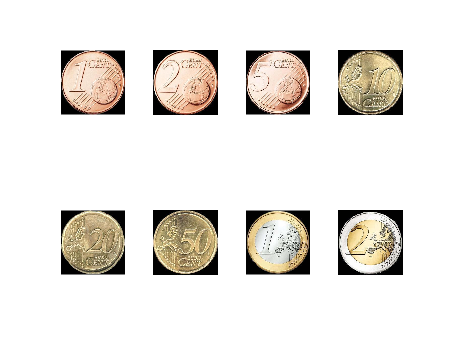

% Mehr Daten generieren
iterations = 1000;
for i = 1:8
    path = generateTestData(i-1, iterations);
    subplot(2,4,i);
    imshow(imread(path));
end

% Laden und Labeln
datasetPath = 'Dataset/';
imds = imageDatastore(datasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Unterteilen in Trainings- und Validierungsdaten
numTrainFiles = 750;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, 'randomized');

% Netzwerkarchitektur definieren
inputSize = [256 256 3];
numClasses = 8;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


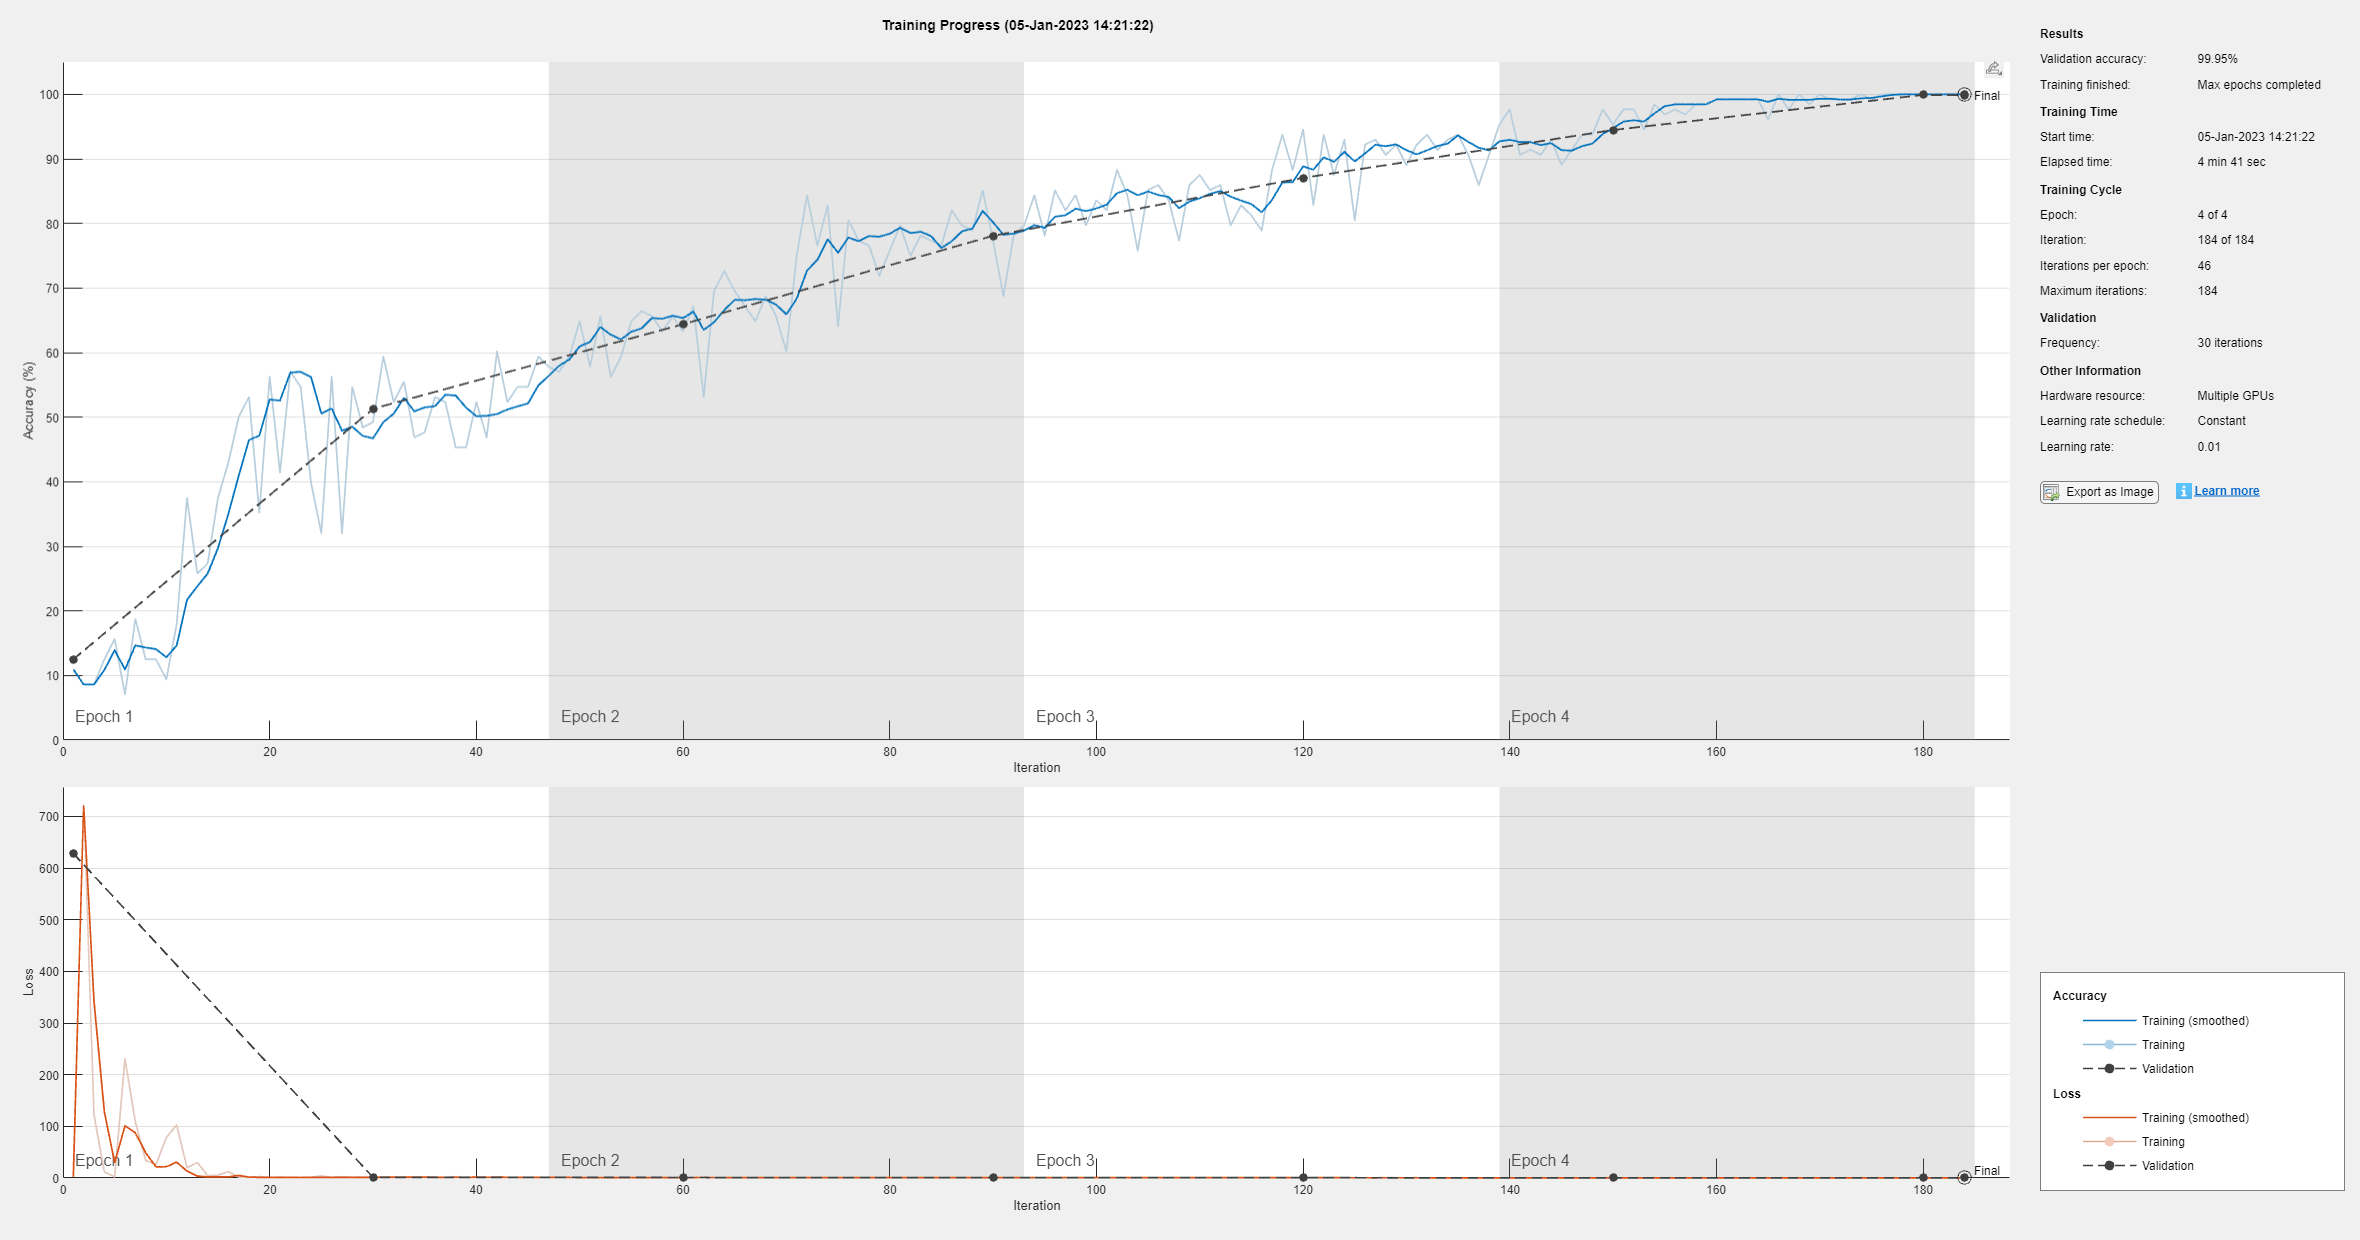

% Netzwerk trainieren
options = trainingOptions('sgdm', 'MaxEpochs', 4,'ValidationData', imdsValidation, ...
    'ValidationFrequency', 30, 'Verbose', false, 'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'parallel');

net = trainNetwork(imdsTrain, layers, options);

serializedNet = net;
save serializedNet;

% Netzwerk laden
load serializedNet
net = serializedNet;

% Netzwerk testen
YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9995

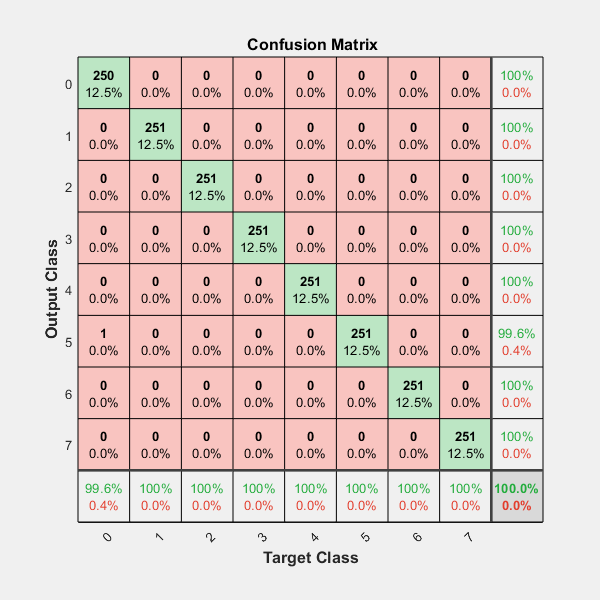

% plotconfusion(YValidation, YPred);


serializedNet = net;
% save serializedNet;

% Input-Bilder abgleichen
imdsTest = imageDatastore(fullfile('readCoins'), IncludeSubfolders=true);
%imdsTest = imdsValidation;
[YTest, scores] = classify(net, imdsTest);
scores

scores = 11×8 single matrix
    0.2097    0.0644    0.0693    0.2208    0.1351    0.1821    0.0603    0.0583
    0.2077    0.0650    0.0688    0.2206    0.1353    0.1827    0.0605    0.0593
    0.6972    0.0115    0.0282    0.0370    0.0141    0.1943    0.0170    0.0006
    0.2185    0.0852    0.0540    0.2320    0.1258    0.1797    0.0402    0.0647
    0.2099    0.0648    0.0688    0.2205    0.1350    0.1824    0.0602    0.0583
    0.2413    0.0610    0.0603    0.2095    0.1394    0.1859    0.0558    0.0469
    0.2093    0.0639    0.0692    0.2215    0.1352    0.1821    0.0604    0.0585
    0.3207    0.0040    0.0752    0.1747    0.0518    0.2078    0.1659    0.0000
    0.2093    0.0639    0.0692    0.2215    0.1352    0.1821    0.0604    0.0585
    0.2103    0.0630    0.0697    0.2217    0.1345    0.1828    0.0614    0.0566


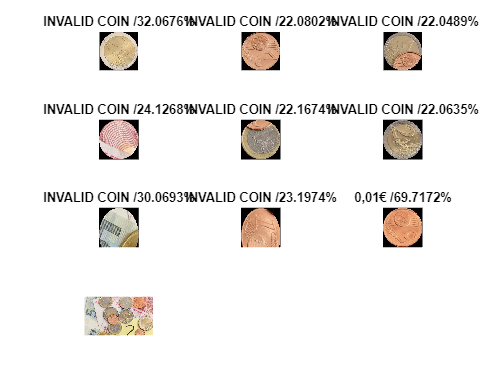

numImages = 10; %12 %10
idx = randperm(numel(imdsTest.Files), numImages);
tiledlayout('flow')
total = 0;
for i=1:numImages
    nexttile
    imshow(imdsTest.Files{idx(i)});  
    chance = max(scores(idx(i),:)) * 100;
    title(strcat(label2name(YTest(idx(i)), chance/100, 0.5), ' / ', num2str(chance), '%'))
    total = total + label2decimal(YTest(idx(i)), chance/100, 0.5);
    % Einspeisen ins Dictionary
end


display(strcat('Total:', sprintf('%0.2f', total), '€'));

Total:0.01€


function origPath = generateTestData(index, iterations)
    rng(0, 'twister');
    path = sprintf('Dataset/%01d/', index);
    origPath = strcat(path, 'orig.jpg');
    I = imresize(imread(origPath), [256 256]);
    imwrite(I, origPath, 'jpg');

    for i = 1:iterations
        angle = randi([0, 359],1,1);
        In = imrotate(I, angle);
        
        targetSize = [256 256];
        win = centerCropWindow2d(size(In), targetSize);
        In = imcrop(In, win);

        str = fullfile(path,  sprintf('generatedData_%03d.jpg', i));
        imwrite(In, str, 'jpg');
    end
end

function res = label2name(label, score, t)
    if (score < t)
        res = 'INVALID COIN';
    else
        switch (string(label))
            case '0'
                res = '0,01€';
            case '1'
                res = '0,02€';
            case '2'
                res = '0,05€';
            case '3'
                res = '0,10€';
            case '4'
                res = '0,20€';
            case '5'
                res = '0,50€';
            case '6'
                res = '1,00€';
            case '7'
                res = '2,00€';
        end
    end
end

function res = label2decimal(label, score, t)
    if (score < t)
        res = 0;
    else
        switch (string(label))
            case '0'
                res = 0.01;
            case '1'
                res = 0.02;
            case '2'
                res = 0.05;
            case '3'
                res = 0.1;
            case '4'
                res = 0.2;
            case '5'
                res = 0.5;
            case '6'
                res = 1;
            case '7'
                res = 2;
        end
    end
end